ansImg=imread("answer.jpg") %input the Correct answer image

ansImg = 611×473×3 uint8 array
ansImg(:,:,1) =

    83    84    94    81    78    97    86    82    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    

testImg=imread("test1.jpg") %input the test image

testImg = 611×473×3 uint8 array
testImg(:,:,1) =

    83    84    94    81    78    97    86    82    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86  

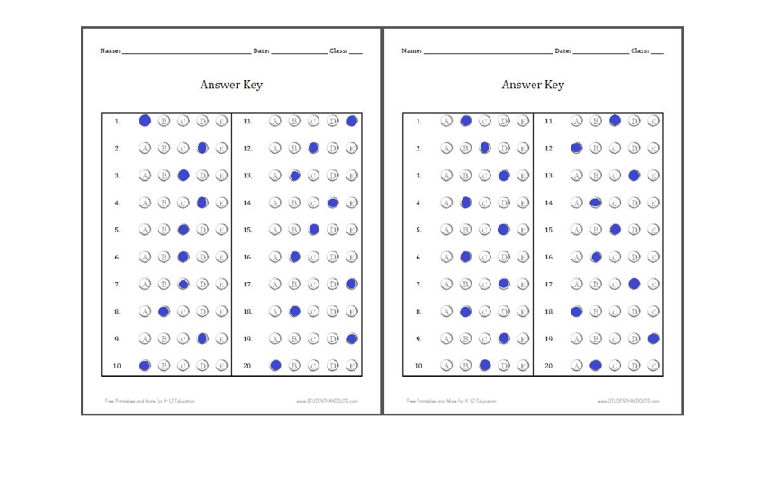

montage({ansImg,testImg});

%--------------------------------------------------------------------------
% Create Mask by Thresholding  test image
[BW] = createMask(testImg)

BW = 611×473 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

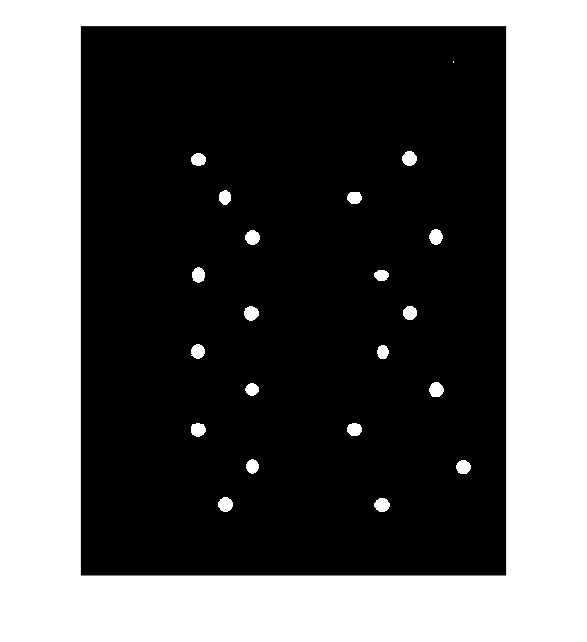

imshow (BW)

%--------------------------------------------------------------------------
% Overlay created test image mask over answer image
masked=ansImg

masked = 611×473×3 uint8 array
masked(:,:,1) =

    83    84    94    81    78    97    86    82    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    

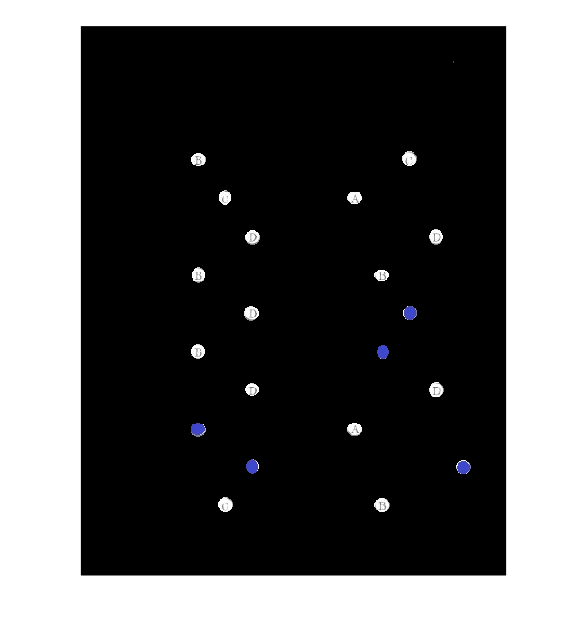

masked(repmat(~BW,1,1,3))=0;
imshow(masked)


%--------------------------------------------------------------------------

% Segment the image to get only empty circles means uncorrect answer
[maskedImage] = segmentImage(masked)

maskedImage = 611×473×3 uint8 array
maskedImage(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

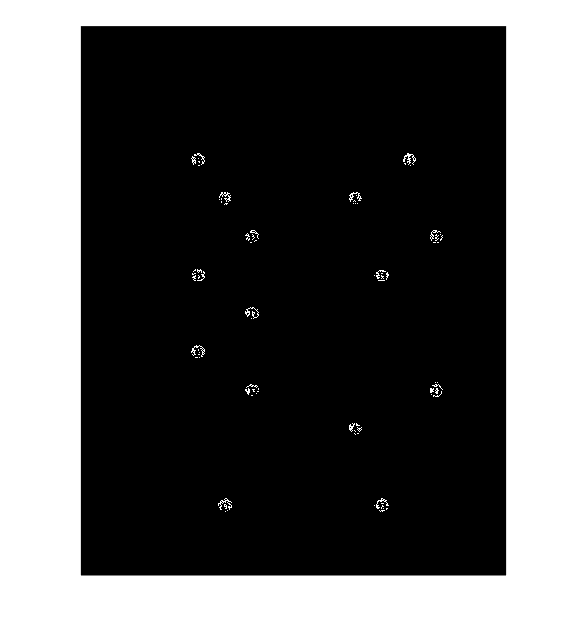

imshow(maskedImage)


[maskedImage] = segmentImageCloseCircles(maskedImage)

maskedImage = 611×473 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

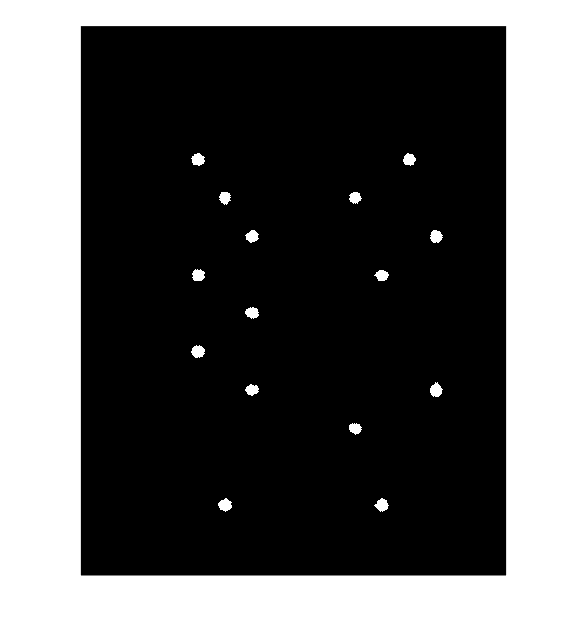

imshow(maskedImage)

%----------------------------------------------------------------------------------------------------
 % Detect circles (marks)
[wrongAnswerCenters, wrongAnswerRadii] = imfindcircles(maskedImage, [6 30], 'ObjectPolarity', 'bright', 'Sensitivity', 0.9);

% wrong answer coordinates(position) has been stored -- in wrongAnswerCenters 

%---------------------------------------------------------------------------------------------------
%----Create a copy of test image-------
newImage=testImg

newImage = 611×473×3 uint8 array
newImage(:,:,1) =

    83    84    94    81    78    97    86    82    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86

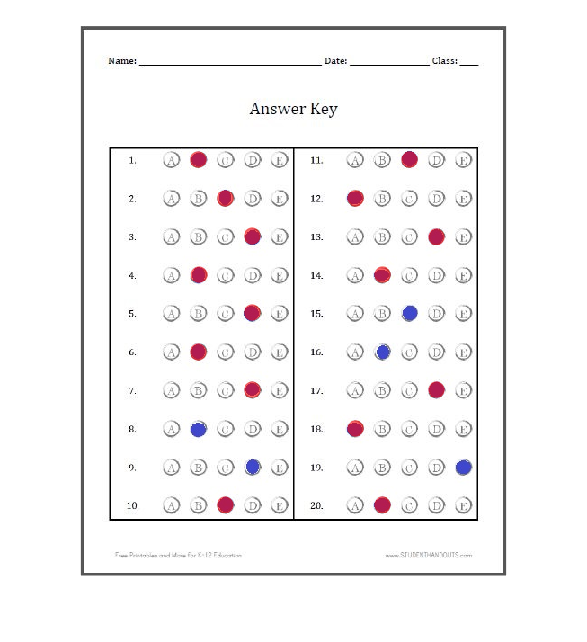

%----------------------
% Hide wrong answer with red color on new image
for i = 1:length(wrongAnswerRadii)
    newImage = insertShape(newImage, 'filled-circle', [wrongAnswerCenters(i, :) wrongAnswerRadii(i)+2], 'Color', 'red');
end

% Step 4: Display the final image
imshow(newImage);


%-----------------------------------------------------------------------------------------------------

[correctAnswerBinaryImage] = createMaskCorrectAnswer(newImage)

correctAnswerBinaryImage = 611×473 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

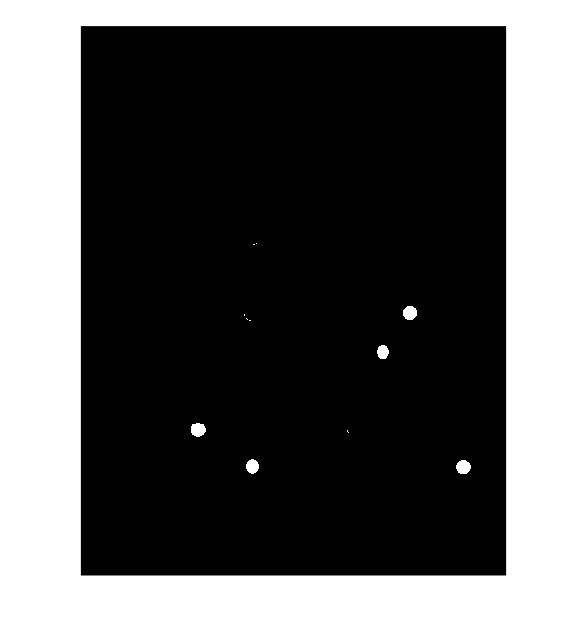


imshow(correctAnswerBinaryImage)

%------------------------------------------------------------------------------------------------------

% Detect correct answer circles 
[correctAnswerCenters, correctAnswerRadii] = imfindcircles(correctAnswerBinaryImage, [6 30], 'ObjectPolarity', 'bright', 'Sensitivity', 0.9);

%------------------------------------------------------------------------------------------------------


correctAnswer=length(correctAnswerRadii)

correctAnswer = 5

wrongAnswer=length(wrongAnswerRadii)

wrongAnswer = 15

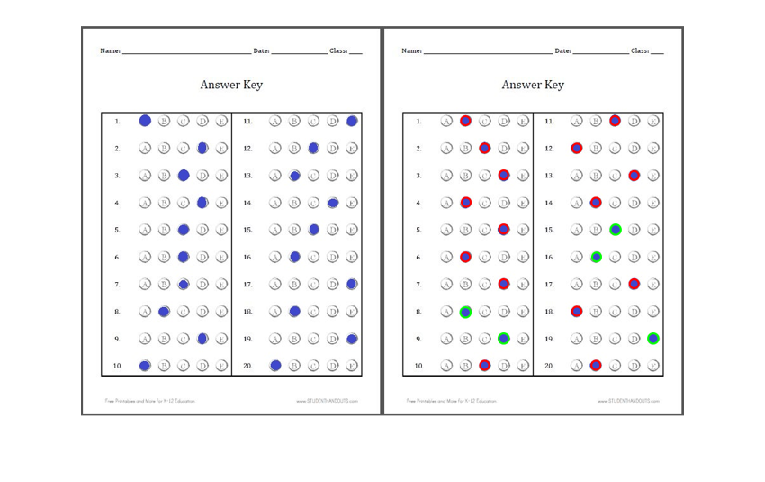




%To detect invalid answer
invalidCircles=[];
invalidRadii=[];
countLine=0;
countTotal=0;
flag=0;
for i = 1:length(correctAnswerRadii)
    for j = 1:length(wrongAnswerRadii)
        
            x1 = correctAnswerCenters(i, 1); 
            y1 = correctAnswerCenters(i, 2);
            x2 = wrongAnswerCenters(j, 1); 
            y2 = wrongAnswerCenters(j, 2);
       
           
        r1=correctAnswerRadii(i);
        r2=wrongAnswerRadii(j);
        if y1-3 <= y2 && y2 <= y1+3
            if (93<x1 && x1 <230) && (93<x2 && x2<230)
                flag=1;
                invalidCircles=[invalidCircles;x1 y1];
                invalidRadii=[invalidRadii;r1];
                invalidCircles=[invalidCircles;x2 y2];
                invalidRadii=[invalidRadii;r2];
                countTotal=countTotal+1;
            end
            if (295 < x1 && x1 < 435) && (295 < x2 && x2 < 435)
                flag=1;
                invalidCircles=[invalidCircles;x1 y1];
                invalidRadii=[invalidRadii;r1];
                invalidCircles=[invalidCircles;x2 y2];
                invalidRadii=[invalidRadii;r2];
                countTotal=countTotal+1;
            end
            
        end
        
    end
    if flag ==1
        countLine=countLine+1;
        flag=0;
    end
end


%-------------------------------------------------------------------------------------------------------
copyImage=testImg;
% Highlight all answers with different colors on copy image
for i = 1:length(wrongAnswerRadii)
    copyImage = insertShape(copyImage, 'Circle', [wrongAnswerCenters(i, :) wrongAnswerRadii(i)], 'Color', 'red','LineWidth', 3);
end



%-----------------------------------------------------------------------------------------------------

for i = 1:length(correctAnswerRadii)
    copyImage = insertShape(copyImage, 'Circle', [correctAnswerCenters(i, :) correctAnswerRadii(i)], 'Color', 'green', 'LineWidth', 3);
end

%------------------------------------------------------------------------------------------------------


for i = 1:length(invalidRadii)
    copyImage = insertShape(copyImage, 'Circle', [invalidCircles(i, :) invalidRadii(i)], 'Color', 'yellow', 'LineWidth', 3);
end




%------------------------------------------------------------------------------------------------------
montage({ansImg,copyImage})




disp("Number of invalid answers:");

Number of invalid answers:


disp(countLine)

     0



disp("Total Score:");

Total Score:


disp(correctAnswer-countLine)

     5

